## Calibrate IMU Direction

clear all;
mobilLurusPath = 'lurus_blokT_asrama.csv';
mobilLurus = readtable(mobilLurusPath)

mobilLurus = 1689×95 table
    gps__class     gps__device      gps__ecefpAcc    gps__ecefvAcc    gps__ecefvx    gps__ecefvy    gps__ecefvz    gps__ecefx     gps__ecefy    gps__ecefz     gps__epc    gps__eph    gps__eps    gps__ept    gps__epv    gps__epx    gps__epy    gps__geoidSep    gps__lat    gps__leapseconds    gps__lon    gps__magvar    gps__mode    gps__sep    gps__speed    gps__status             gps__time              i2c__barometer__altitude    i2c__barometer__pressure    i2c__barome

depan: 


$$\begin{array}{l}
x^B =-y^{\textrm{IMU}} \\
y^B =-x^{\textrm{IMU}} \\
z^B =z^{\textrm{IMU}} 
\end{array}$$


kanan (steer):


$$\begin{array}{l}
x^B =-y^{\textrm{IMU}} \\
y^B =-x^{\textrm{IMU}} \\
z^B =z^{\textrm{IMU}} 
\end{array}$$


kiri:


$$\begin{array}{l}
x^B =y^{\textrm{IMU}} \\
y^B =x^{\textrm{IMU}} \\
z^B =z^{\textrm{IMU}} 
\end{array}$$


belakang:


$$\begin{array}{l}
x^B =-x^{\textrm{IMU}} \\
y^B =y^{\textrm{IMU}} \\
z^B =z^{\textrm{IMU}} 
\end{array}$$


#### Show Axes plot for each IMU to get direction

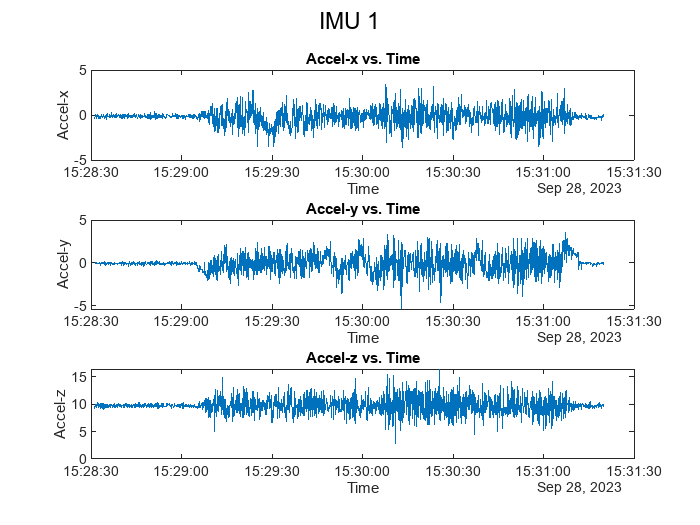

tbl2subplot(mobilLurus, {'i2c__imu1__accel__x', 'i2c__imu1__accel__y', 'i2c__imu1__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 1');

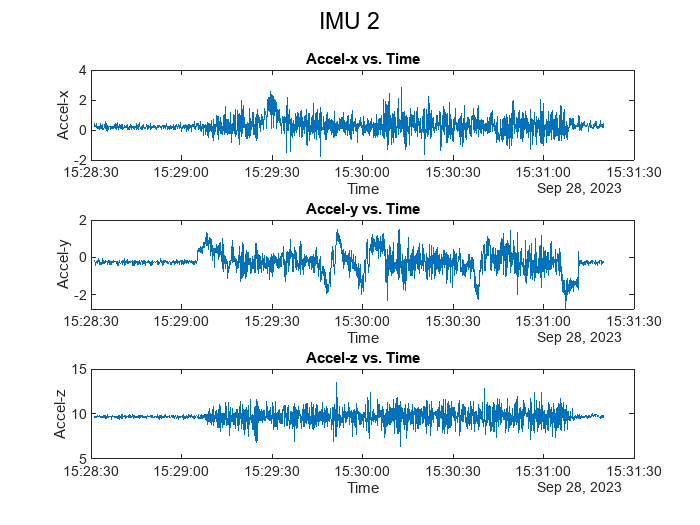

tbl2subplot(mobilLurus, {'i2c__imu2__accel__x', 'i2c__imu2__accel__y', 'i2c__imu2__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 2');

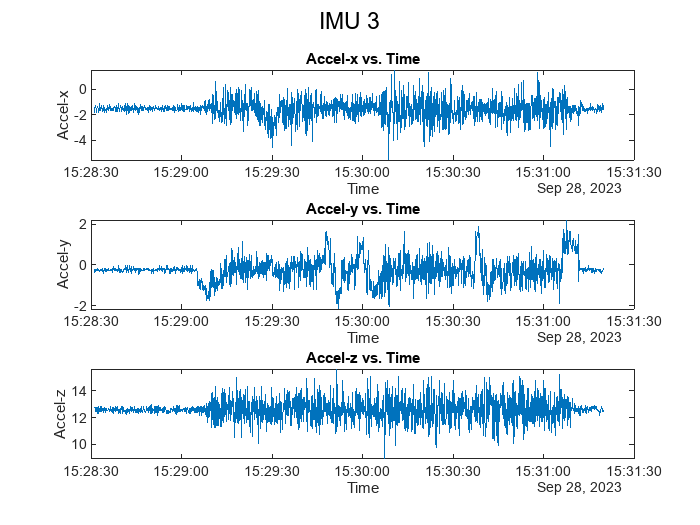

tbl2subplot(mobilLurus, {'i2c__imu3__accel__x', 'i2c__imu3__accel__y', 'i2c__imu3__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 3');

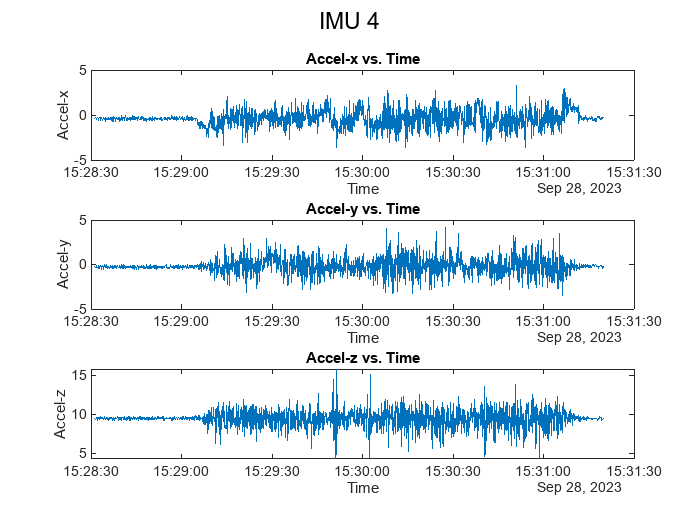

tbl2subplot(mobilLurus, {'i2c__imu4__accel__x', 'i2c__imu4__accel__y', 'i2c__imu4__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 4');

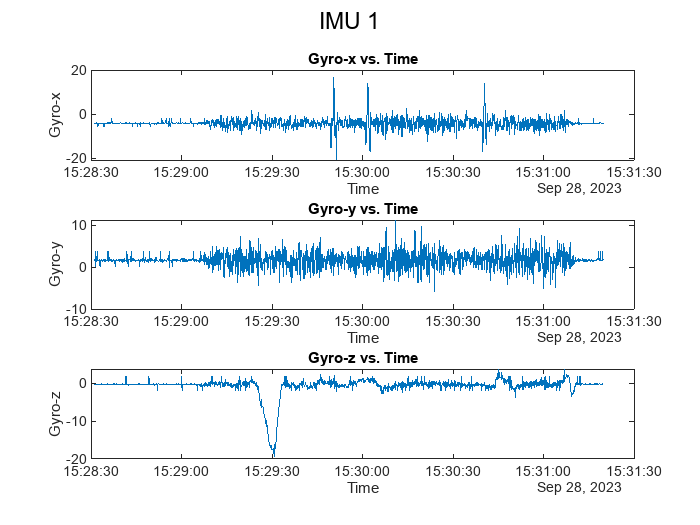


tbl2subplot(mobilLurus, {'i2c__imu1__gyro__x', 'i2c__imu1__gyro__y', 'i2c__imu1__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 1');

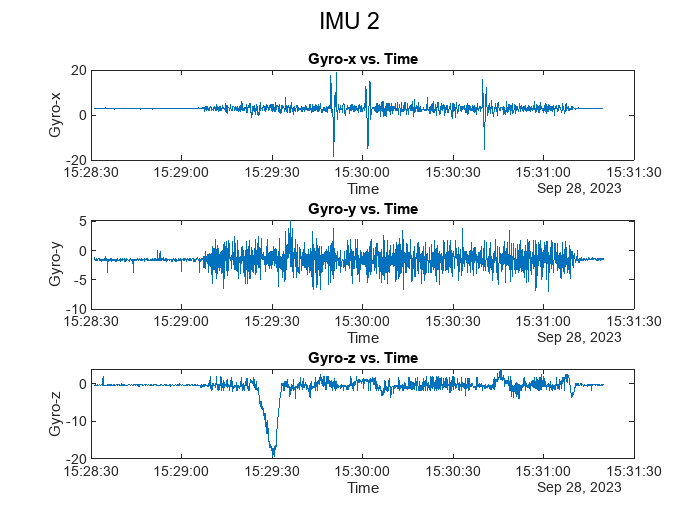

tbl2subplot(mobilLurus, {'i2c__imu2__gyro__x', 'i2c__imu2__gyro__y', 'i2c__imu2__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 2');

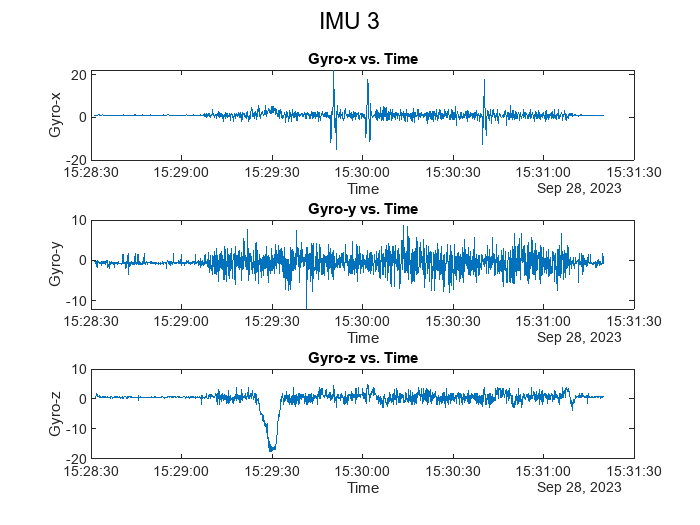

tbl2subplot(mobilLurus, {'i2c__imu3__gyro__x', 'i2c__imu3__gyro__y', 'i2c__imu3__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 3');

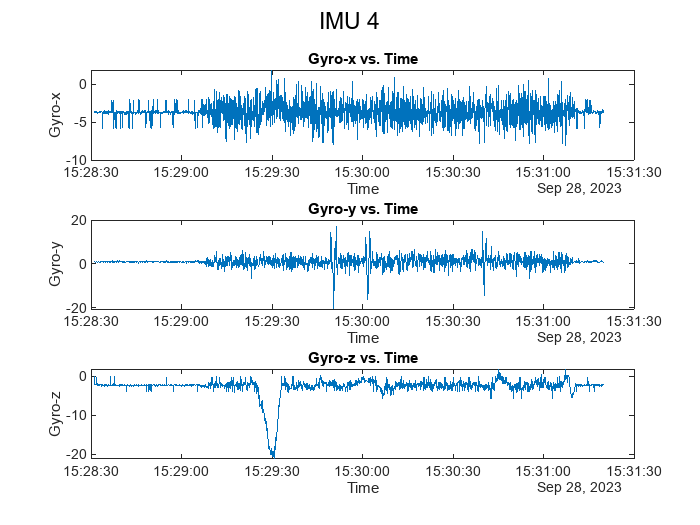

tbl2subplot(mobilLurus, {'i2c__imu4__gyro__x', 'i2c__imu4__gyro__y', 'i2c__imu4__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 4');

#### Normalize direction

mobilLurus = norm4imu(mobilLurus);

Show Fixed Plot

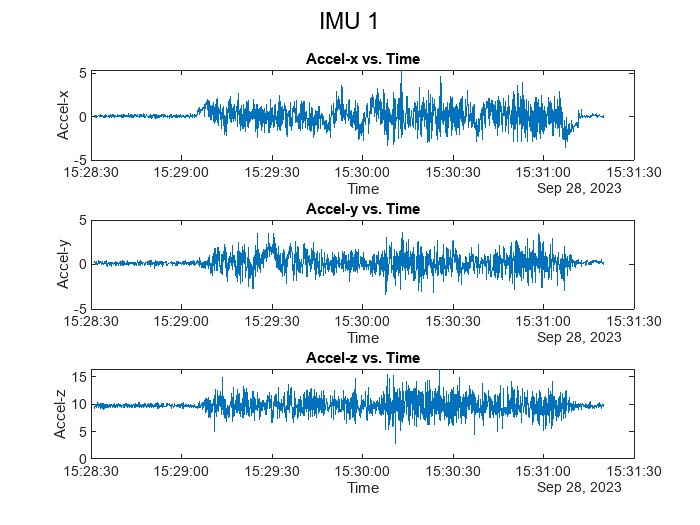

tbl2subplot(mobilLurus, {'i2c__bimu1__accel__x', 'i2c__bimu1__accel__y', 'i2c__bimu1__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 1');

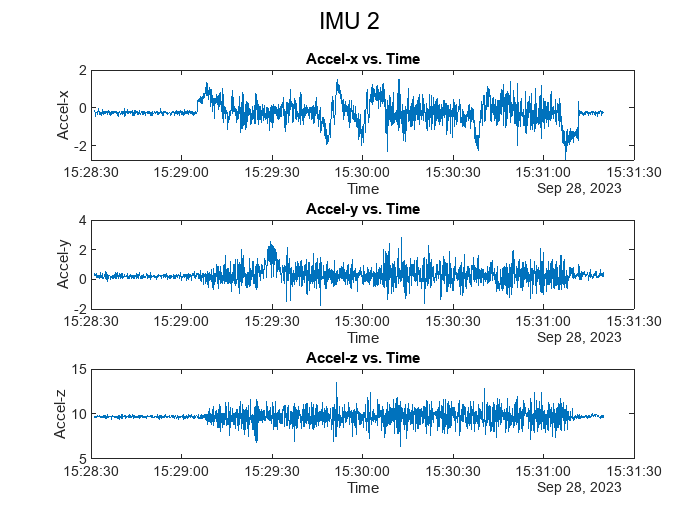

tbl2subplot(mobilLurus, {'i2c__bimu2__accel__x', 'i2c__bimu2__accel__y', 'i2c__bimu2__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 2');

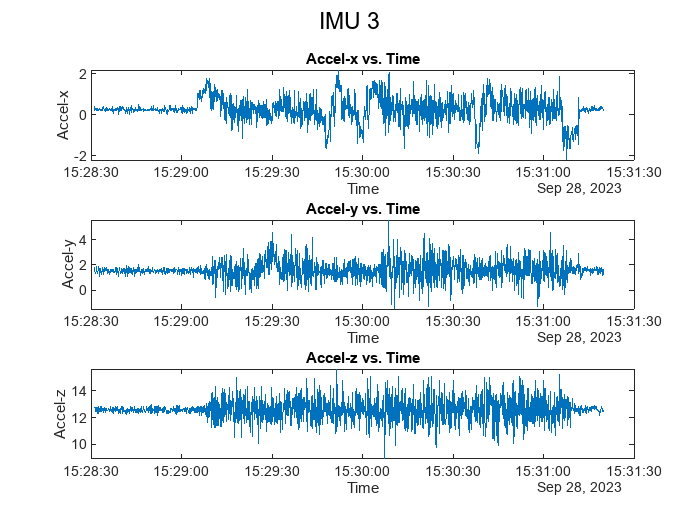

tbl2subplot(mobilLurus, {'i2c__bimu3__accel__x', 'i2c__bimu3__accel__y', 'i2c__bimu3__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 3');

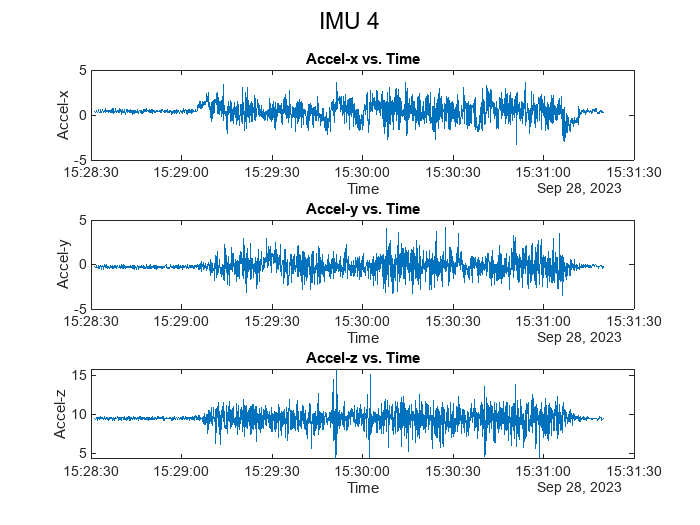

tbl2subplot(mobilLurus, {'i2c__bimu4__accel__x', 'i2c__bimu4__accel__y', 'i2c__bimu4__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 4');

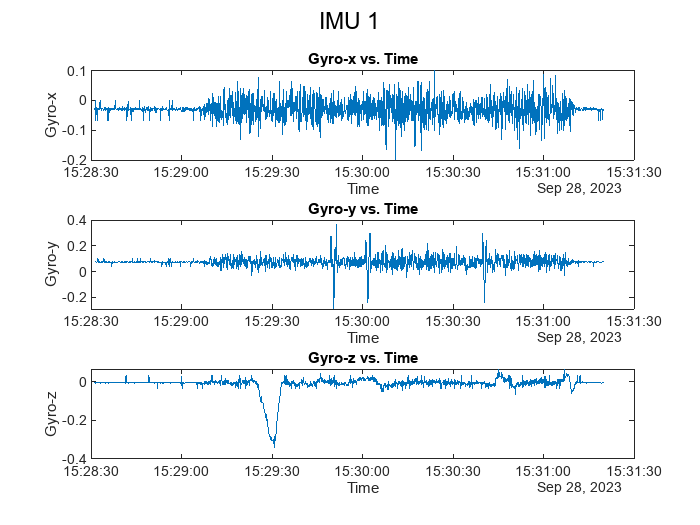


tbl2subplot(mobilLurus, {'i2c__bimu1__gyro__x', 'i2c__bimu1__gyro__y', 'i2c__bimu1__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 1');

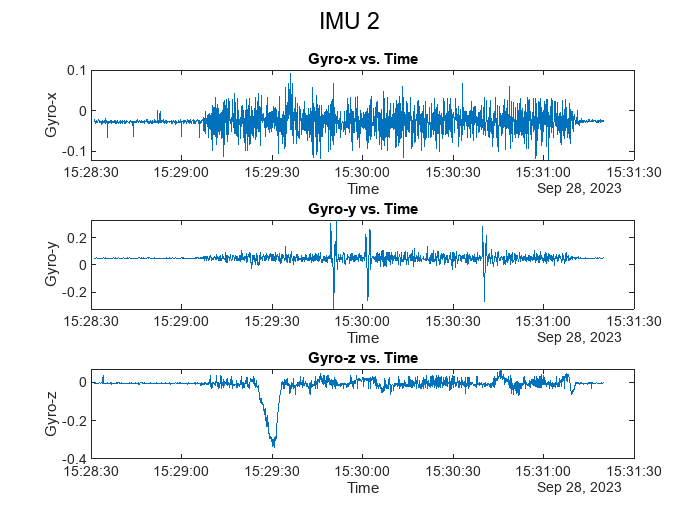

tbl2subplot(mobilLurus, {'i2c__bimu2__gyro__x', 'i2c__bimu2__gyro__y', 'i2c__bimu2__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 2');

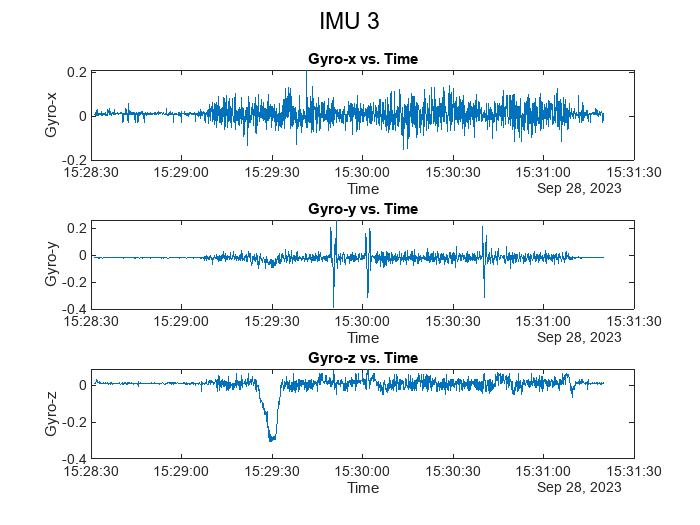

tbl2subplot(mobilLurus, {'i2c__bimu3__gyro__x', 'i2c__bimu3__gyro__y', 'i2c__bimu3__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 3');

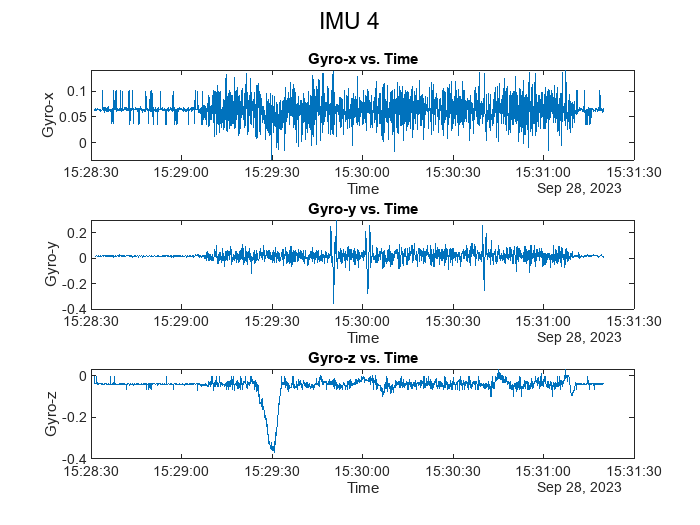

tbl2subplot(mobilLurus, {'i2c__bimu4__gyro__x', 'i2c__bimu4__gyro__y', 'i2c__bimu4__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 4');

## Find Bias (Mean) and Sensor Variance

% clear all; clc;

mobilDiamV1Path = 'mobil_diam_v1.csv';
mobilDiamV1 = readtable(mobilDiamV1Path);
mobilDiamV1 = norm4imu(mobilDiamV1);

mobilDiamV2Path = 'mobil_diam_v2.csv';
mobilDiamV2 = readtable(mobilDiamV2Path);
mobilDiamV2 = norm4imu(mobilDiamV2);

### Preprocessing

convert gps__time and i2c__timestamp to matlab time

gpsTimeStr = mobilDiamV1.gps__time;
i2cTimeStr = mobilDiamV1.i2c__timestamp;

gpsTime = datetime(gpsTimeStr, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSS''Z''');
i2cTime = datetime(i2cTimeStr, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSS''Z''');

mobilDiamV1.gps__time = gpsTime;
mobilDiamV1.i2c__timestamp = i2cTime

mobilDiamV1 = 2788×119 table
    gps__class     gps__device      gps__ecefpAcc    gps__ecefvAcc    gps__ecefvx    gps__ecefvy    gps__ecefvz    gps__ecefx     gps__ecefy    gps__ecefz     gps__epc    gps__eph    gps__eps    gps__ept    gps__epv    gps__epx    gps__epy    gps__geoidSep    gps__lat    gps__leapseconds    gps__lon    gps__magvar    gps__mode    gps__sep    gps__speed    gps__status         gps__time          i2c__barometer__altitude    i2c__barometer__pressure    i2c__barometer__t

gpsTimeStr = mobilDiamV2.gps__time;
i2cTimeStr = mobilDiamV2.i2c__timestamp;

gpsTime = datetime(gpsTimeStr, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSS''Z''');
i2cTime = datetime(i2cTimeStr, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSS''Z''');

mobilDiamV2.gps__time = gpsTime;
mobilDiamV2.i2c__timestamp = i2cTime

mobilDiamV2 = 1996×119 table
    gps__class     gps__device      gps__ecefpAcc    gps__ecefvAcc    gps__ecefvx    gps__ecefvy    gps__ecefvz    gps__ecefx     gps__ecefy    gps__ecefz     gps__epc    gps__eph    gps__eps    gps__ept    gps__epv    gps__epx    gps__epy    gps__geoidSep    gps__lat    gps__leapseconds    gps__lon    gps__magvar    gps__mode    gps__sep    gps__speed    gps__status         gps__time          i2c__barometer__altitude    i2c__barometer__pressure    i2c__barometer__t

remove row if any of accel measurement is zero

% Define the column names for the accelerometer measurements for all IMUs
imu_columns = {
    'i2c__bimu1__accel__x', 'i2c__bimu1__accel__y', 'i2c__bimu1__accel__z',
    'i2c__bimu2__accel__x', 'i2c__bimu2__accel__y', 'i2c__bimu2__accel__z',
    'i2c__bimu3__accel__x', 'i2c__bimu3__accel__y', 'i2c__bimu3__accel__z',
    'i2c__bimu4__accel__x', 'i2c__bimu4__accel__y', 'i2c__bimu4__accel__z',
    'i2c__bimu1__gyro__x', 'i2c__bimu1__gyro__y', 'i2c__bimu1__gyro__z',
    'i2c__bimu2__gyro__x', 'i2c__bimu2__gyro__y', 'i2c__bimu2__gyro__z',
    'i2c__bimu3__gyro__x', 'i2c__bimu3__gyro__y', 'i2c__bimu3__gyro__z',
    'i2c__bimu4__gyro__x', 'i2c__bimu4__gyro__y', 'i2c__bimu4__gyro__z',
};

% Check if all columns exist in the table
missing_columns1 = ~ismember(imu_columns, mobilDiamV1.Properties.VariableNames);
missing_columns2 = ~ismember(imu_columns, mobilDiamV2.Properties.VariableNames);

if any(missing_columns1)
    missing_column_names = imu_columns(missing_columns1);
    fprintf('The following columns are missing: %s\n', strjoin(missing_column_names, ', '));
else
    % Find rows where any of the accelerometer measurements is zero for all IMUs
    zero_accel_rows = any(mobilDiamV1{:, imu_columns} == 0, 2);

    % Remove rows with zero accelerometer measurements
    mobilDiamV1 = mobilDiamV1(~zero_accel_rows, :);
end

if any(missing_columns2)
    missing_column_names = imu_columns(missing_columns2);
    fprintf('The following columns are missing: %s\n', strjoin(missing_column_names, ', '));
else
    % Find rows where any of the accelerometer measurements is zero for all IMUs
    zero_accel_rows = any(mobilDiamV2{:, imu_columns} == 0, 2);

    % Remove rows with zero accelerometer measurements
    mobilDiamV2 = mobilDiamV2(~zero_accel_rows, :);
end

## Plot Mobil Diam v1 IMU data

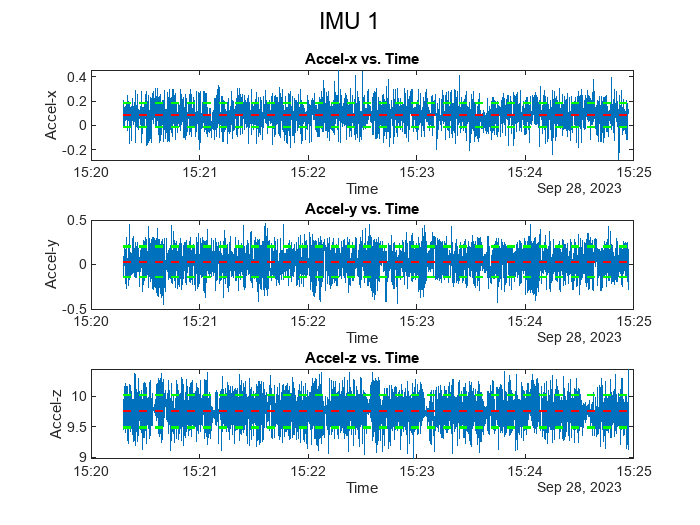

imu_name = {'imu1', 'imu2', 'imu3', 'imu4'};
axisname = {'acc-x mean', 'acc-y mean', 'acc-z mean', ...
            'gyro-x mean', 'gyro-y mean', 'gyro-z mean', ...
            'acc-x var', 'acc-y var', 'acc-z var', ...
            'gyro-x var', 'gyro-y var', 'gyro-z var'};
mv1 = zeros(size(axisname,2), size(imu_name,2));

fig = figure;
set(fig, 'Position', [100, 100, 800, 400]);
[mv1(1:3,1), mv1(7:9,1)] = tbl2subplots(mobilDiamV1, {'i2c__bimu1__accel__x', 'i2c__bimu1__accel__y', 'i2c__bimu1__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 1');

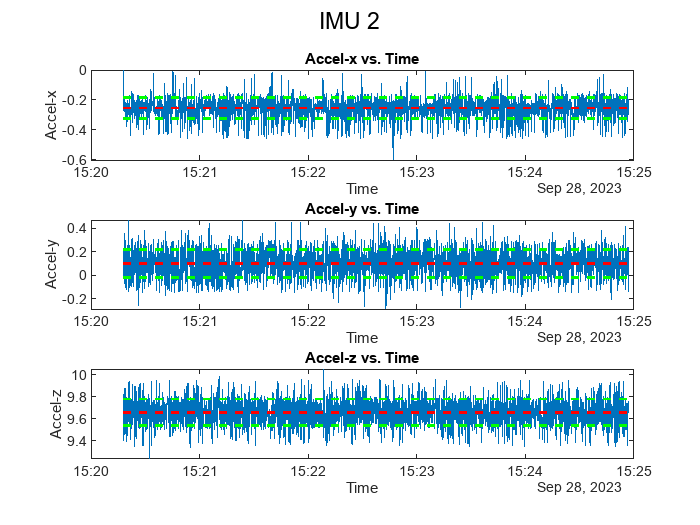

[mv1(1:3,2), mv1(7:9,2)] = tbl2subplots(mobilDiamV1, {'i2c__bimu2__accel__x', 'i2c__bimu2__accel__y', 'i2c__bimu2__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 2');

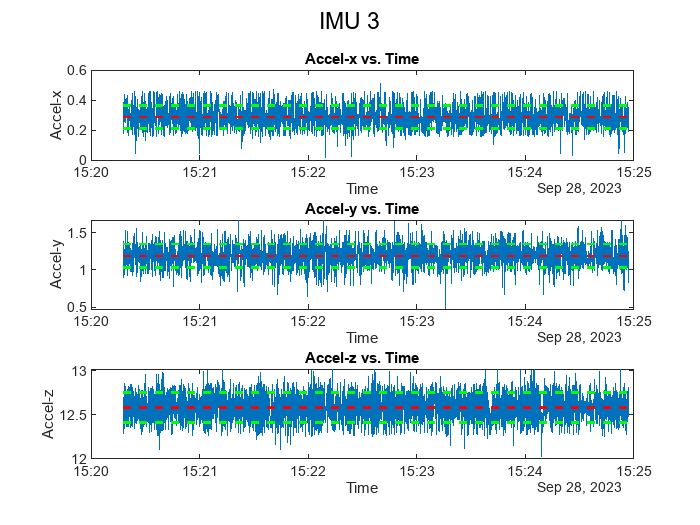

[mv1(1:3,3), mv1(7:9,3)] = tbl2subplots(mobilDiamV1, {'i2c__bimu3__accel__x', 'i2c__bimu3__accel__y', 'i2c__bimu3__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 3');

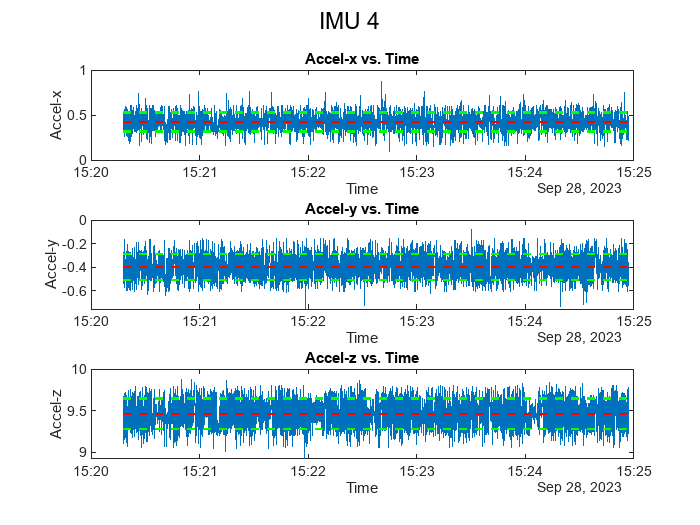

[mv1(1:3,4), mv1(7:9,4)] = tbl2subplots(mobilDiamV1, {'i2c__bimu4__accel__x', 'i2c__bimu4__accel__y', 'i2c__bimu4__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 4');

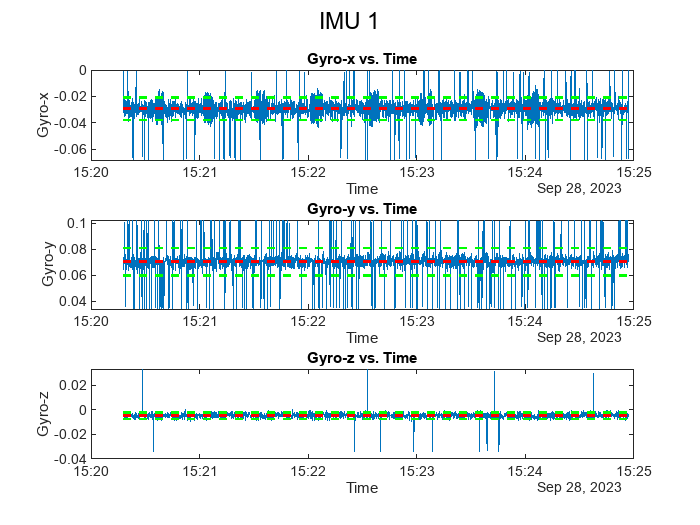


[mv1(4:6,1), mv1(10:12,1)] = tbl2subplots(mobilDiamV1, {'i2c__bimu1__gyro__x', 'i2c__bimu1__gyro__y', 'i2c__bimu1__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 1');

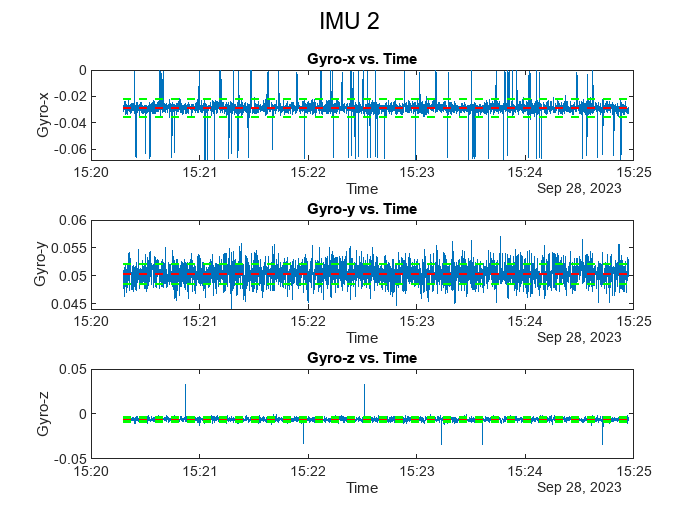

[mv1(4:6,2), mv1(10:12,2)] = tbl2subplots(mobilDiamV1, {'i2c__bimu2__gyro__x', 'i2c__bimu2__gyro__y', 'i2c__bimu2__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 2');

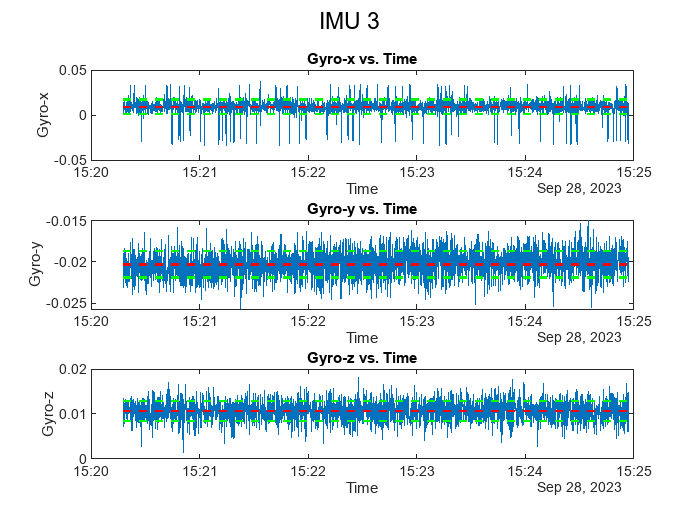

[mv1(4:6,3), mv1(10:12,3)] = tbl2subplots(mobilDiamV1, {'i2c__bimu3__gyro__x', 'i2c__bimu3__gyro__y', 'i2c__bimu3__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 3');

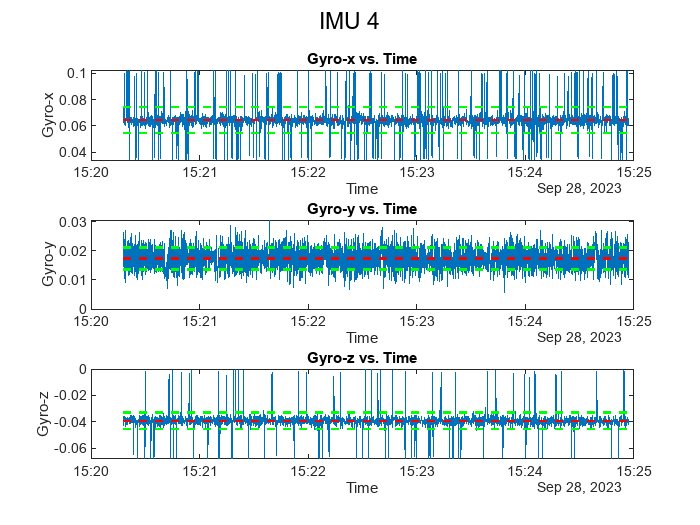

[mv1(4:6,4), mv1(10:12,4)] = tbl2subplots(mobilDiamV1, {'i2c__bimu4__gyro__x', 'i2c__bimu4__gyro__y', 'i2c__bimu4__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 4');


% Create the table with imu_name as row names and axisname as column names
data_table1 = array2table(mv1, 'RowNames', axisname, 'VariableNames', imu_name);

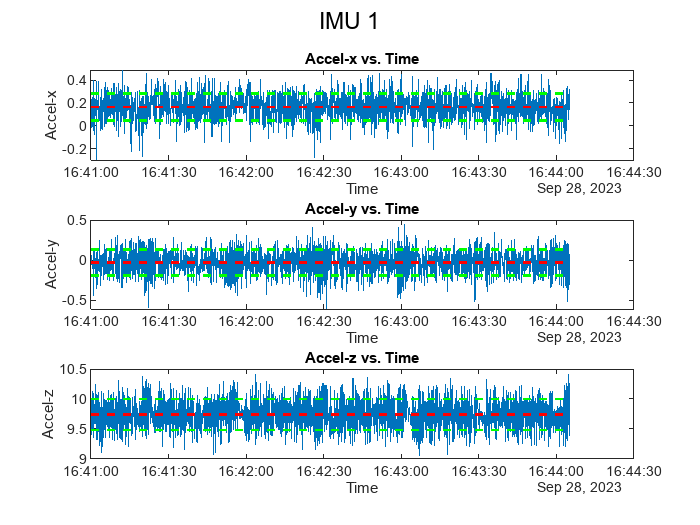

mv2 = zeros(size(axisname,2), size(imu_name,2));

[mv2(1:3,1), mv2(7:9,1)] = tbl2subplots(mobilDiamV2, {'i2c__bimu1__accel__x', 'i2c__bimu1__accel__y', 'i2c__bimu1__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 1');

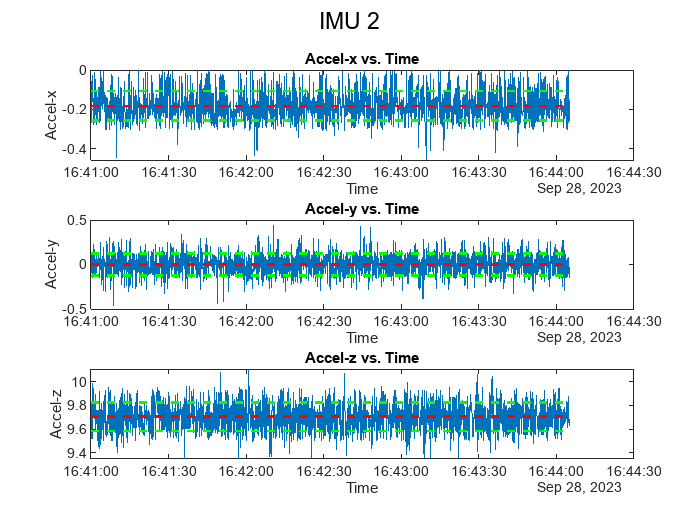

[mv2(1:3,2), mv2(7:9,2)] = tbl2subplots(mobilDiamV2, {'i2c__bimu2__accel__x', 'i2c__bimu2__accel__y', 'i2c__bimu2__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 2');

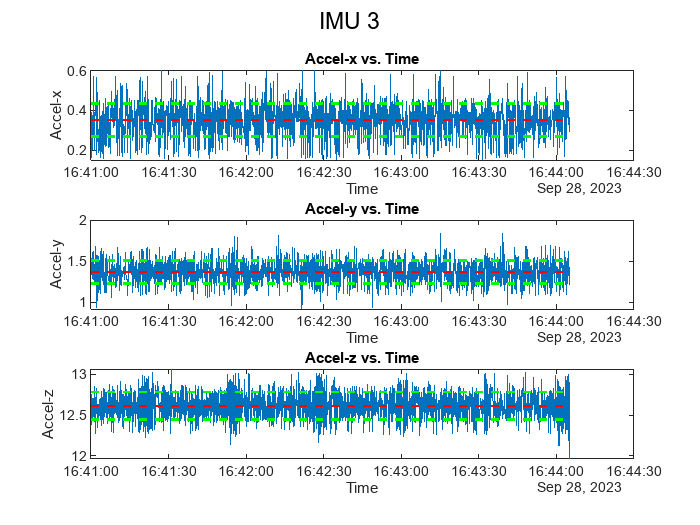

[mv2(1:3,3), mv2(7:9,3)] = tbl2subplots(mobilDiamV2, {'i2c__bimu3__accel__x', 'i2c__bimu3__accel__y', 'i2c__bimu3__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 3');

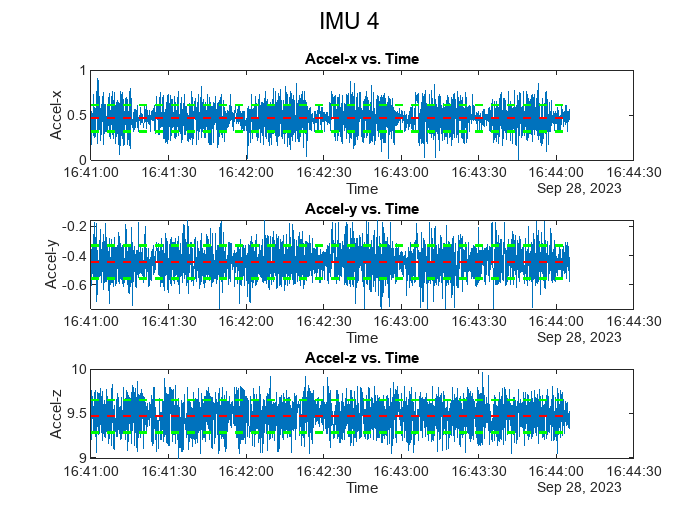

[mv2(1:3,4), mv2(7:9,4)] = tbl2subplots(mobilDiamV2, {'i2c__bimu4__accel__x', 'i2c__bimu4__accel__y', 'i2c__bimu4__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 4');

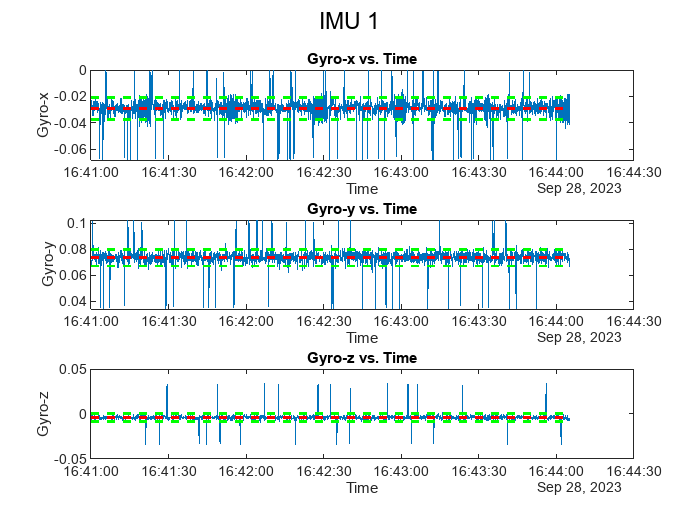


[mv2(4:6,1), mv2(10:12,1)] = tbl2subplots(mobilDiamV2, {'i2c__bimu1__gyro__x', 'i2c__bimu1__gyro__y', 'i2c__bimu1__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 1');

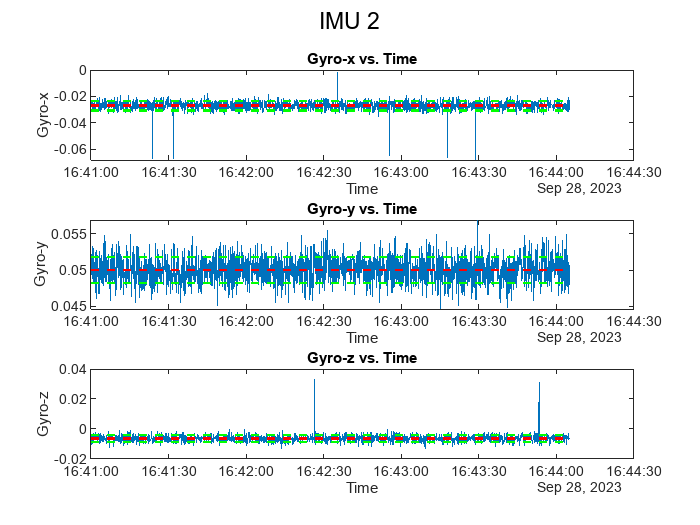

[mv2(4:6,2), mv2(10:12,2)] = tbl2subplots(mobilDiamV2, {'i2c__bimu2__gyro__x', 'i2c__bimu2__gyro__y', 'i2c__bimu2__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 2');

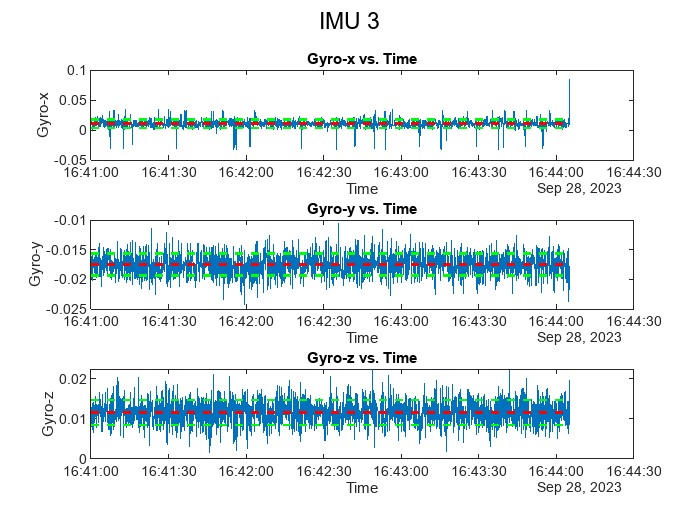

[mv2(4:6,3), mv2(10:12,3)] = tbl2subplots(mobilDiamV2, {'i2c__bimu3__gyro__x', 'i2c__bimu3__gyro__y', 'i2c__bimu3__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 3');

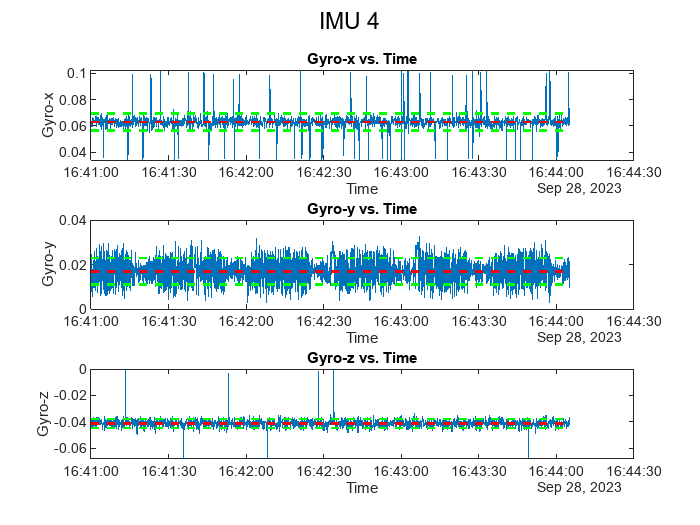

[mv2(4:6,4), mv2(10:12,4)] = tbl2subplots(mobilDiamV2, {'i2c__bimu4__gyro__x', 'i2c__bimu4__gyro__y', 'i2c__bimu4__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 4');


% Create the table with imu_name as row names and axisname as column names
data_table2 = array2table(mv2, 'RowNames', axisname, 'VariableNames', imu_name);

% Display the table
disp(data_table1);

                      imu1          imu2          imu3          imu4   
                   __________    __________    __________    __________

    acc-x mean       0.086053      -0.25586       0.28661       0.42109
    acc-y mean       0.030597      0.097764        1.1896      -0.39859
    acc-z mean         9.7562        9.6579        12.585        9.4622
    gyro-x mean     -0.029182     -0.028795     0.0089608      0.064385
    gyro-y mean      0.070388      0.050376     -0.020288      0.017387
    gyro-z mean    -0.0047093    -0.0060399      0.010663     -0.039244
    acc-x var        0.010044     0.0050264     0.0060141      0.011119
    acc-y var        0.028795      0.014088      0.024418      0.012131
    

disp(data_table2);

                      imu1          imu2          imu3          imu4   
                   __________    __________    __________    __________

    acc-x mean         0.1641      -0.18212       0.35204       0.46523
    acc-y mean      -0.031049     0.0011971        1.3702      -0.44247
    acc-z mean          9.742        9.7045        12.614        9.4683
    gyro-x mean     -0.029117     -0.027073      0.010465      0.062977
    gyro-y mean      0.073498      0.050022      -0.01751      0.016866
    gyro-z mean    -0.0038251    -0.0062799      0.011568     -0.041133
    acc-x var        0.013702     0.0057322     0.0070755      0.021859
    acc-y var        0.026466      0.015243      0.019337      0.012763
    

% save MV as bias corrector
save("calibrate_value.mat","mv1",'-mat');

% clear
% aa = load("calibrate_value.mat", "mv1");
% aa.mv1

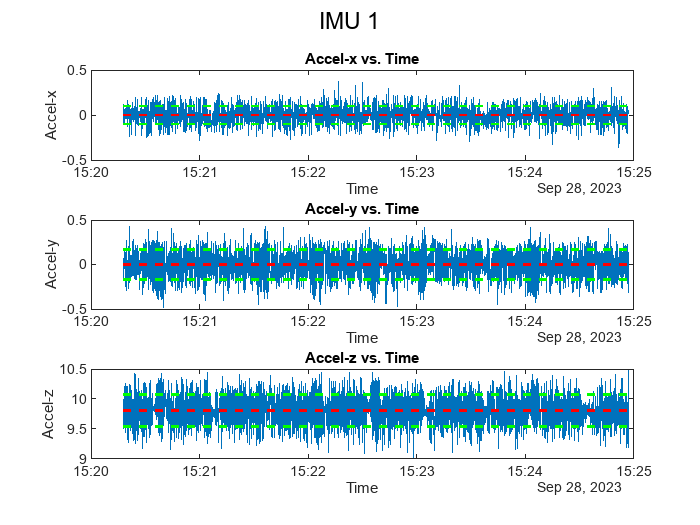

mobilDiamV1 = correction4imu("calibrate_value.mat", mobilDiamV1);
mv3 = zeros(size(axisname,2), size(imu_name,2));

[mv3(1:3,1), mv3(7:9,1)] = tbl2subplots(mobilDiamV1, {'i2c__cimu1__accel__x', 'i2c__cimu1__accel__y', 'i2c__cimu1__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 1');

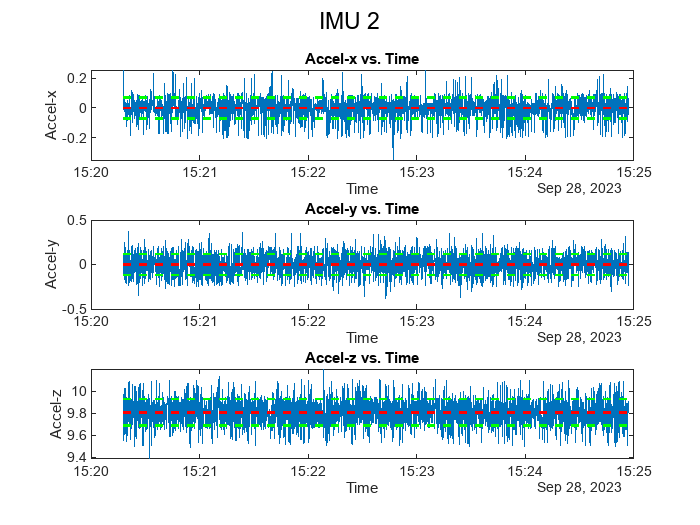

[mv3(1:3,2), mv3(7:9,2)] = tbl2subplots(mobilDiamV1, {'i2c__cimu2__accel__x', 'i2c__cimu2__accel__y', 'i2c__cimu2__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 2');

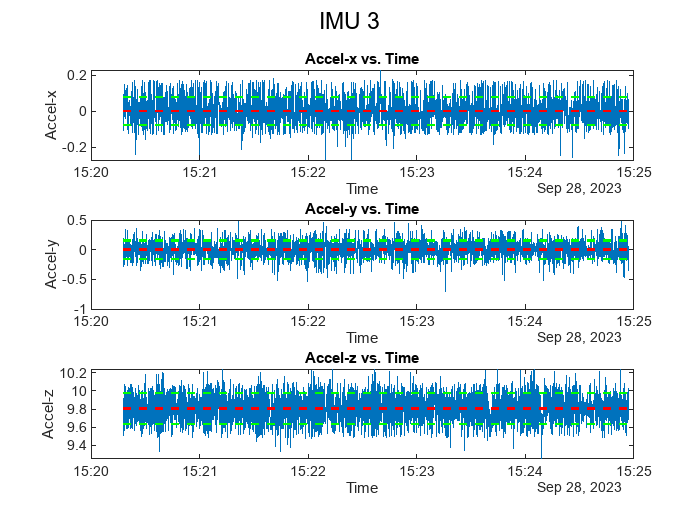

[mv3(1:3,3), mv3(7:9,3)] = tbl2subplots(mobilDiamV1, {'i2c__cimu3__accel__x', 'i2c__cimu3__accel__y', 'i2c__cimu3__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 3');

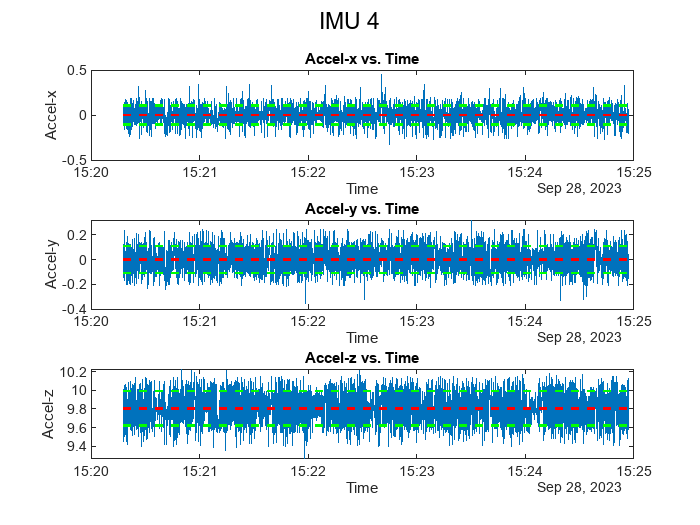

[mv3(1:3,4), mv3(7:9,4)] = tbl2subplots(mobilDiamV1, {'i2c__cimu4__accel__x', 'i2c__cimu4__accel__y', 'i2c__cimu4__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 4');

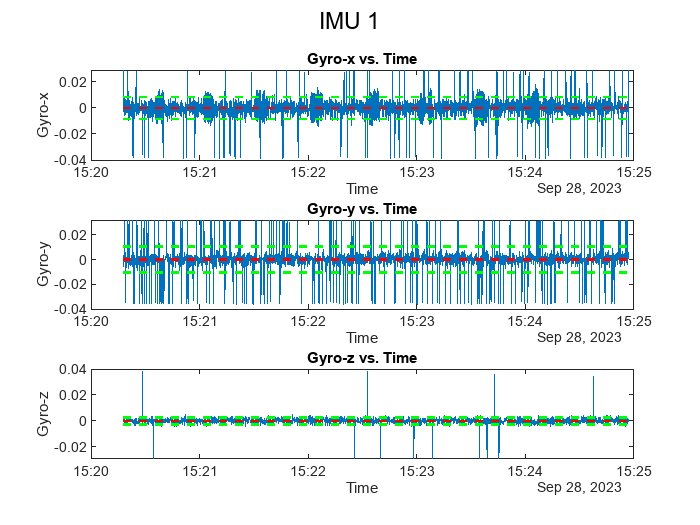


[mv3(4:6,1), mv3(10:12,1)] = tbl2subplots(mobilDiamV1, {'i2c__cimu1__gyro__x', 'i2c__cimu1__gyro__y', 'i2c__cimu1__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 1');

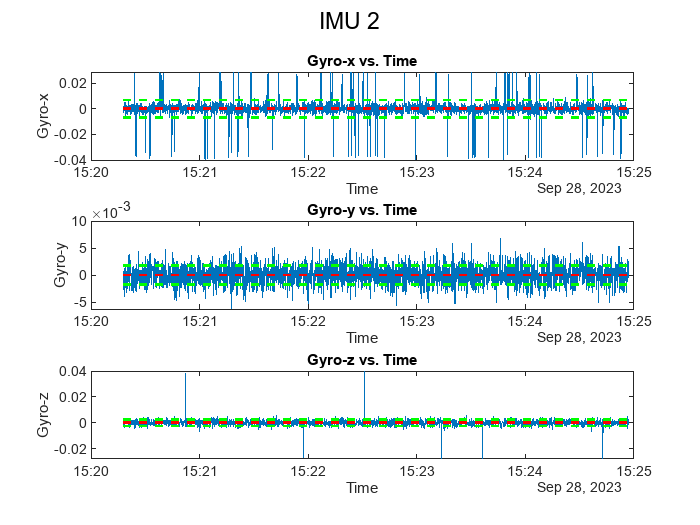

[mv3(4:6,2), mv3(10:12,2)] = tbl2subplots(mobilDiamV1, {'i2c__cimu2__gyro__x', 'i2c__cimu2__gyro__y', 'i2c__cimu2__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 2');

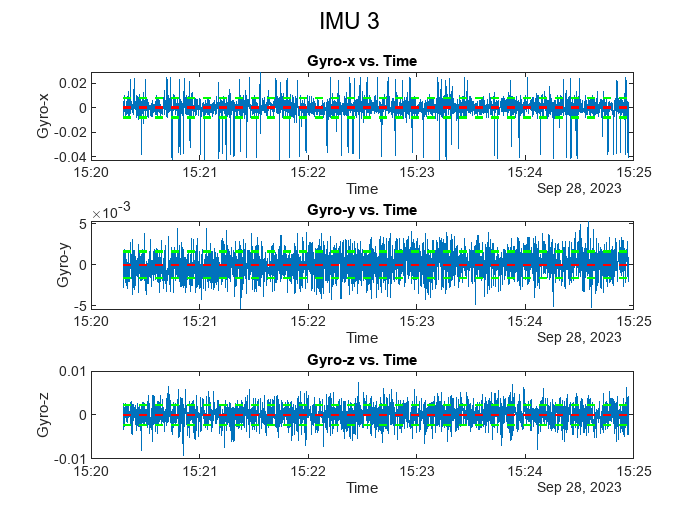

[mv3(4:6,3), mv3(10:12,3)] = tbl2subplots(mobilDiamV1, {'i2c__cimu3__gyro__x', 'i2c__cimu3__gyro__y', 'i2c__cimu3__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 3');

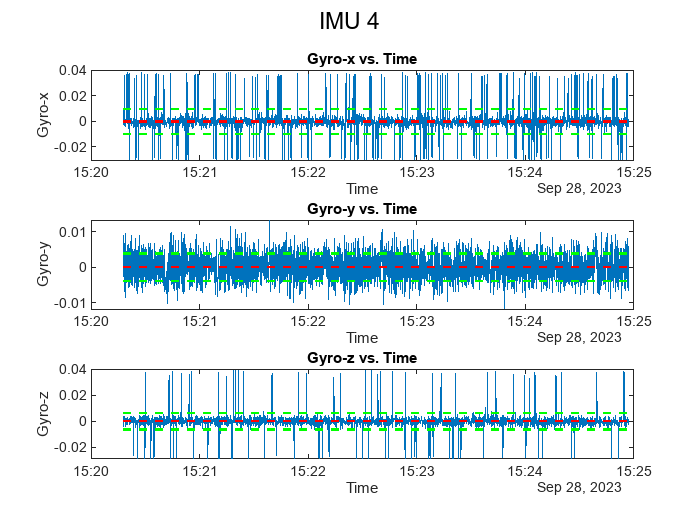

[mv3(4:6,4), mv3(10:12,4)] = tbl2subplots(mobilDiamV1, {'i2c__cimu4__gyro__x', 'i2c__cimu4__gyro__y', 'i2c__cimu4__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 4');


% Create the table with imu_name as row names and axisname as column names
data_table3 = array2table(mv3, 'RowNames', axisname, 'VariableNames', imu_name);

% Display the table
disp(data_table3);

                      imu1           imu2           imu3           imu4   
                   ___________    ___________    ___________    __________

    acc-x mean     -1.3045e-17     1.8183e-16    -2.2131e-16    1.8934e-16
    acc-y mean     -7.3121e-19     5.2972e-17     5.0145e-16    3.1621e-16
    acc-z mean          9.8067         9.8067         9.8067        9.8067
    gyro-x mean    -1.0521e-17    -1.5376e-17     5.0575e-18     1.698e-17
    gyro-y mean    -4.2898e-17    -2.6334e-17    -4.9934e-18    3.7068e-18
    gyro-z mean    -1.2822e-18    -2.1657e-18    -8.0636e-18    3.8033e-17
    acc-x var         0.010044      0.0050264      0.0060141      0.011119
    acc-y var         0.028795       0.014088       

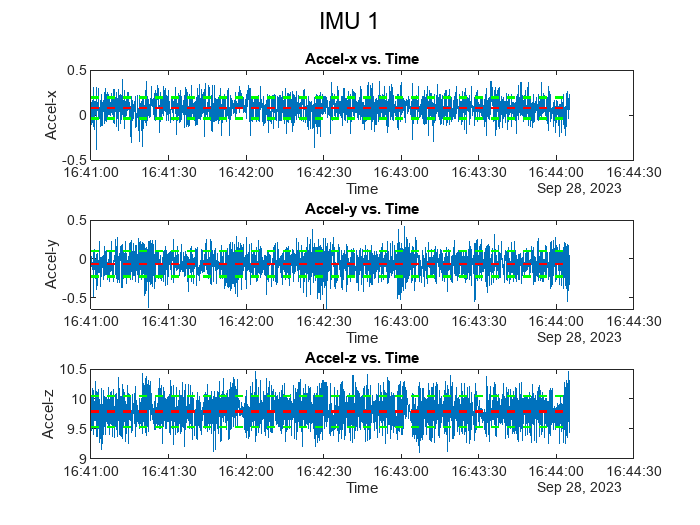

mobilDiamV2 = correction4imu("calibrate_value.mat", mobilDiamV2);
mv4 = zeros(size(axisname,2), size(imu_name,2));

[mv4(1:3,1), mv4(7:9,1)] = tbl2subplots(mobilDiamV2, {'i2c__cimu1__accel__x', 'i2c__cimu1__accel__y', 'i2c__cimu1__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 1');

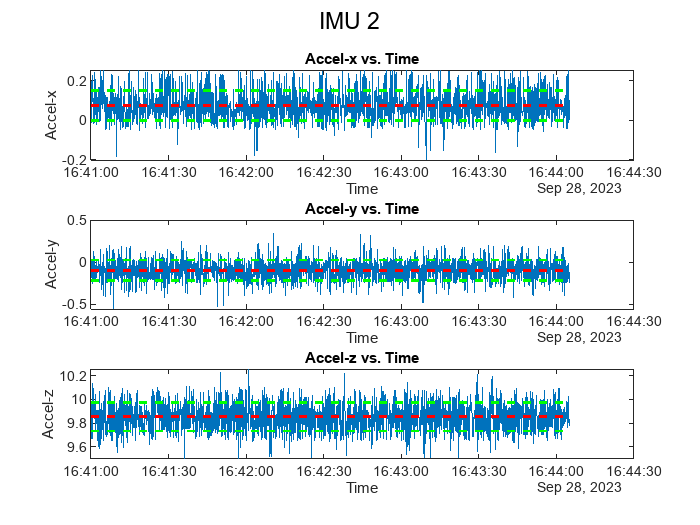

[mv4(1:3,2), mv4(7:9,2)] = tbl2subplots(mobilDiamV2, {'i2c__cimu2__accel__x', 'i2c__cimu2__accel__y', 'i2c__cimu2__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 2');

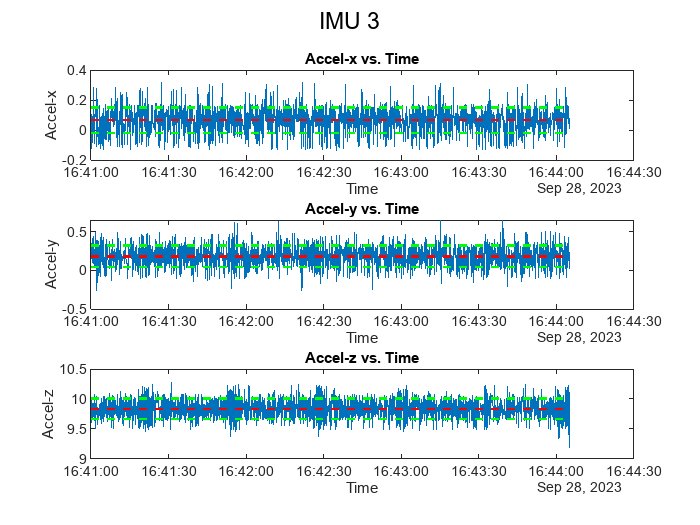

[mv4(1:3,3), mv4(7:9,3)] = tbl2subplots(mobilDiamV2, {'i2c__cimu3__accel__x', 'i2c__cimu3__accel__y', 'i2c__cimu3__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 3');

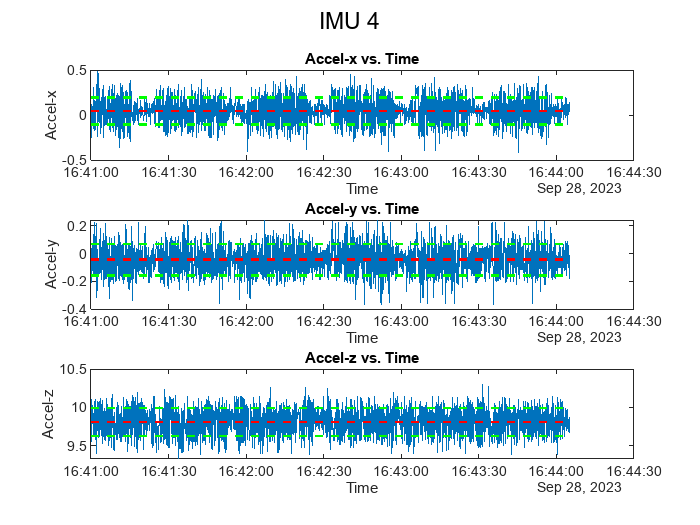

[mv4(1:3,4), mv4(7:9,4)] = tbl2subplots(mobilDiamV2, {'i2c__cimu4__accel__x', 'i2c__cimu4__accel__y', 'i2c__cimu4__accel__z'}, 'i2c__timestamp', {'Accel-x', 'Accel-y', 'Accel-z'}, 'IMU 4');


[mv4(4:6,1), mv4(10:12,1)] = tbl2subplots(mobilDiamV2, {'i2c__cimu1__gyro__x', 'i2c__cimu1__gyro__y', 'i2c__cimu1__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 1');

[mv4(4:6,2), mv4(10:12,2)] = tbl2subplots(mobilDiamV2, {'i2c__cimu2__gyro__x', 'i2c__cimu2__gyro__y', 'i2c__cimu2__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 2');

[mv4(4:6,3), mv4(10:12,3)] = tbl2subplots(mobilDiamV2, {'i2c__cimu3__gyro__x', 'i2c__cimu3__gyro__y', 'i2c__cimu3__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 3');

[mv4(4:6,4), mv4(10:12,4)] = tbl2subplots(mobilDiamV2, {'i2c__cimu4__gyro__x', 'i2c__cimu4__gyro__y', 'i2c__cimu4__gyro__z'}, 'i2c__timestamp', {'Gyro-x', 'Gyro-y', 'Gyro-z'}, 'IMU 4');


% Create the table with imu_name as row names and axisname as column names
data_table4 = array2table(mv4, 'RowNames', axisname, 'VariableNames', imu_name);

% Display the table
disp(data_table4);

                      imu1          imu2           imu3          imu4    
                   __________    ___________    __________    ___________

    acc-x mean       0.078052       0.073735      0.065426       0.044139
    acc-y mean      -0.061646      -0.096567       0.18065      -0.043874
    acc-z mean         9.7925         9.8533        9.8356         9.8128
    gyro-x mean    6.4259e-05      0.0017224     0.0015047     -0.0014083
    gyro-y mean     0.0031102     -0.0003544     0.0027781    -0.00052063
    gyro-z mean    0.00088425    -0.00023999     0.0009048     -0.0018897
    acc-x var        0.013702      0.0057322     0.0070755       0.021859
    acc-y var        0.026466       0.015243      0.019337   